# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

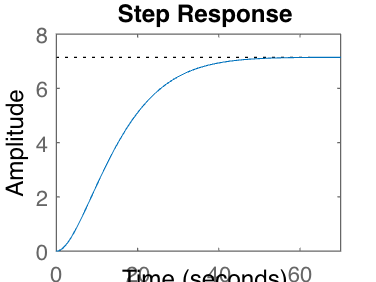

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Km = 0.5;               % torque constant
Kb = 0.1;               % back emf constant
Kf = 0.2;               % Nms viscous friction
J = 10;                 % kg.m^2/s^2

h1 = tf(Km,[L R]);            % armature
h2 = tf(1,[J Kf]);            % eqn of motion

dcm = ss(h2) * [h1 , 1];      % w = h2 * (h1*Va + Td)
dcm = feedback(dcm,Kb,1,1);   % close back emf loop

stepplot(dcm(1));

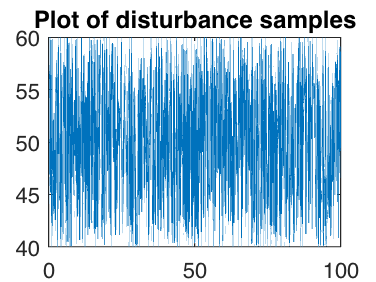


K = 5;
C = K;            % compensator K

Kff = 1/dcgain(dcm(1));
cl_ff = dcm * diag([Kff,1]);    % add feedforward gain
cl_ff.InputName = {'w_ref','Td'};
cl_ff.OutputName = 'w';

% disturbance
Ts = 0.1;
N = 1000;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance

p_switch = 0.5; % white noise PSB distribution
UU = ones(N,1);
for i=2:(N-1)
   if rand(1)<p_switch, UU(i)=-UU(i-1); else UU(i)=UU(i-1); end
end
for i=1:N
    Td(i) = load + deviation*rand(1,1)*UU(i);
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");

u = [ones(size(t)) ; Td];       % w_ref=1 and Td


cl_rloc = feedback(dcm * append(C,1),1,1,1);
h = lsimplot(cl_ff,cl_rloc,u,t);
cl_rloc.InputName = {'w_ref','Td'};
cl_rloc.OutputName = 'w';
title('Setpoint tracking and disturbance rejection')
legend('feedforward','feedback w/ rlocus','Location','NorthWest')

## Problem 2:

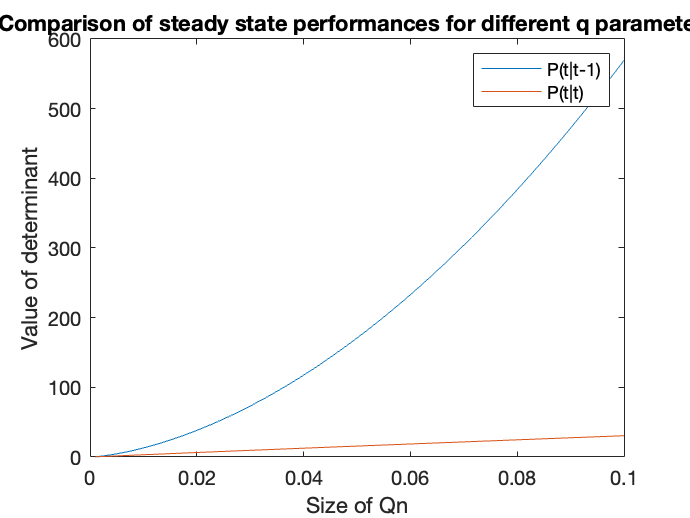

% Find discrete-time model
% Find Kalman filter
% Ts = 20s
% Evaluate predicted and filtered values
Ts = 20;
q_s = 0.001:0.0005:0.1;
P_s = zeros(length(q_s),1);
Z_s = zeros(length(q_s),1);
for i = 1:length(q_s)
    Qn = q_s(i)*eye(size(A,1));
    Rn = Rc*eye(size(C,1));
    [kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
    P_s(i) = det(P); % prediction co-variance p(t|t-1)
    Z_s(i) = det(Z); % filtering co-variance P(t|t)
end
figure(4);
plot(q_s,P_s);
hold on;
plot(q_s,Z_s);
ylabel("Value of determinant");
xlabel("Size of Qn");
title("Comparison of steady state performances for different q parameters");
legend("P(t|t-1)","P(t|t)");

legend show

P_min = 1000000;
for i = 1:length(q_s)
    if (P_s(i)<P_min)
        disp("Found minimum")
        P_min = P_s(i);
        i_min = i;
    end
end

Found minimum


Qn = q_s(i_min)*eye(size(A,1));
Rn = 0.1*eye(size(C,1));
[kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
P %minimal prediction co-variance p(t|t-1)

P =     0.0250    0.0030
    0.0030   62.1751


Z %minimal filtering co-variance P(t|t)

Z =     0.0250    0.0030
    0.0030   62.0517


## Problem 3:

% Find Kalman Filter models
% Use asynchronous sampling with controller computation time
% Tc = 10/1/0.1/s
% Compare properties of noise models
% Evaluate P (predicted value)

Ts = 20;
Tcs = [10 1 0.1];
B = [B G];
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    P
end

Tc


    10



P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Tc


     1



P = 	1.0e+04 *

    0.6902    0.9280
    0.9280    4.0247


Tc


    0.1000



P = 	1.0e+04 *

    0.0714    0.0960
    0.0960    1.0645



%% Conclusion: the longer the Tc, the worse is prediction covariance

## Problem 4:

% Show impact of neglecting S in case of asynchronous sampling
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    disp("With S")
    P
    disp("Value of determinant with S")
    disp(det(P))
    disp("With S=0")
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R);
    P
    disp("Value of determinant without S")
    det(P)
end

Tc


    10



With S


P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Value of determinant with S


   5.5126e+10



With S=0


P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Value of determinant without S


ans = 5.5126e+10

Tc


     1



With S


P = 	1.0e+04 *

    0.6902    0.9280
    0.9280    4.0247


Value of determinant with S


   1.9168e+08



With S=0


P = 	1.0e+04 *

    1.1686    1.5715
    1.5715    6.5784


Value of determinant without S


ans = 5.2181e+08

Tc


    0.1000



With S


P = 	1.0e+04 *

    0.0714    0.0960
    0.0960    1.0645


Value of determinant with S


   6.6816e+06



With S=0


P = 	1.0e+05 *

    0.0767    0.1032
    0.1032    1.1069


Value of determinant without S


ans = 7.4302e+08

%% Conclusion: inclusion of S improves prediction covariance for 10 times for Tc = 0.1

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with not correlated noise (S=0)
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;

Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

A_decor = A - S*inv(R)*C;
B_decor = B - S*inv(R)*D;
Q_decor = Q - S*inv(R)*S';

R = R;

disp("State covariance matrix P(t|t) for system model with decorrelated noise")

State covariance matrix P(t|t) for system model with decorrelated noise



[kest,L,P,M,Z] = kalman(ss(A_decor,B_decor,C,D,Ts),Q_decor,R);
Tc

Tc = 0.1000

Z

Z = 	1.0e+04 *

    9.1118    1.6578
    1.6578    5.5383


det(Z)

ans = 4.7715e+09

% Conclusion:
% The best values of filtering co-variance P(t|t) is achieved with 
% small Tc = 0.1s

## Additional confirmation of working

[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
sys = ss(A,[B G],C,[D 0]);
step_input = ones(1,N+1);
disturbance = [0,W];

noisevec = sqrt(Rc)*randn(N+1,1);
response = lsim(sys,[step_input;disturbance],[0:dt:T]);
y = response+noisevec;

[kest,L,P,M,Z] = kalman(sys,Qc,Rc);
filtered = lsim(kest,[step_input;y'],[0:dt:T]);
figure(5);
plot([0:dt:T],y,'b');
hold on
plot([0:dt:T],filtered(:,1),'r');
title("Noisy and filtered output");
legend("Noisy","Filtered");
hold off

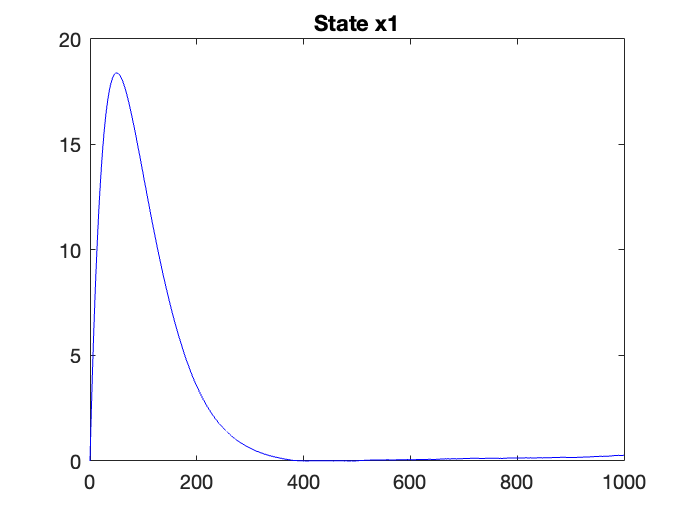


figure(6);

plot([0:dt:T],filtered(:,2),'b');
title("State x1");

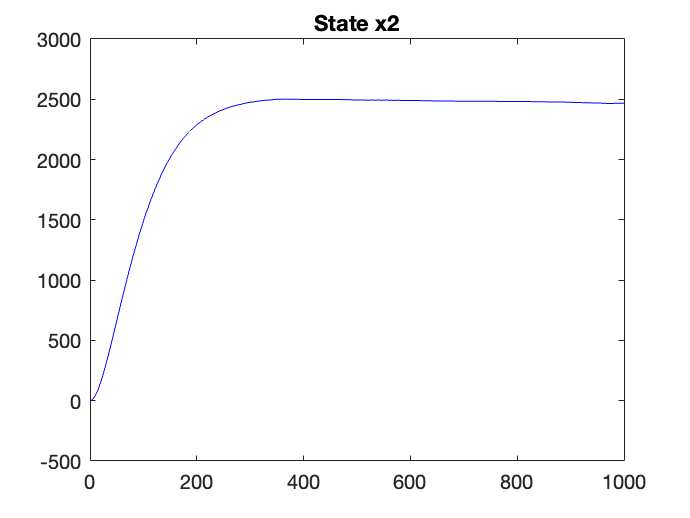


figure(7);
plot([0:dt:T],filtered(:,3),'b');
title("State x2");

## Confirmation of asynchronous sampling wokring

G = [1;0];
B = [B G];
Tc = Tcs(3);
etta = (Ts-Tc)/Ts;
Aasync = expm(A*Ts);
Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Casync = C*expm(A*etta*Ts);
Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
N= T/Ts;
step_input = ones(1,N+1);

% Wiener Process 
N = T/Ts;
dt = Ts;
dW = zeros(1,N);                % preallocate arrays ...
W = zeros(1,N);                 % for efficiency
dW(1) = Qc*sqrt(dt)*randn();    % first approximation outside the loop ...
W(1) = dW(1);                   % since W(0) = 0 is not allowed
for j = 2:N
    dW(j)= Qc*sqrt(dt)*randn(); % general increment
    W(j) = W(j-1) + dW(j);
end
disturbance = [0,W];
sysAsync = ss(Aasync,Basync,Casync,Dasync,Ts);
noisevec = sqrt(Rc)*randn(N+1,1);
response = lsim(sysAsync,[step_input;disturbance],[0:Ts:T]);
y = response+noisevec;
 
Qasync = Qc;
Sasync = Qc;
Rasync = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

[kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Qasync,Rasync,Sasync);
P

P =     0.2184    0.3583
    0.3583  537.1191


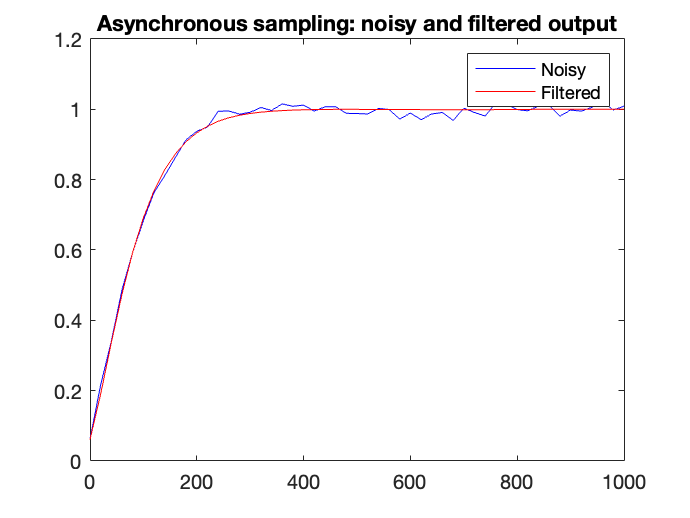

filtered = lsim(kest,[step_input;y'],[0:Ts:T]);
figure(8);
plot([0:dt:T],y,'b');
hold on
plot([0:dt:T],filtered(:,1),'r');
title("Asynchronous sampling: noisy and filtered output");
legend("Noisy","Filtered");
hold off

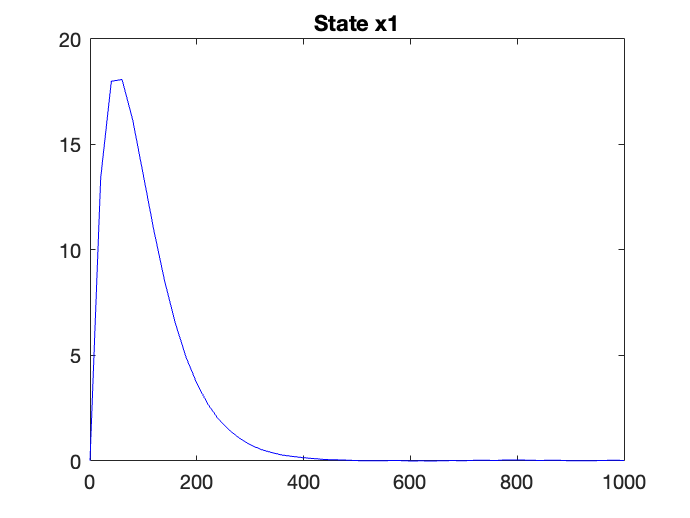


figure(9);
plot([0:dt:T],filtered(:,2),'b');
title("State x1");

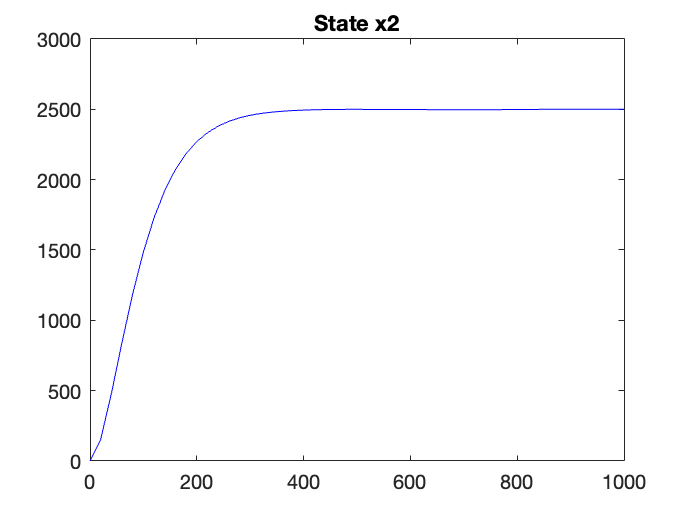


figure(10);
plot([0:dt:T],filtered(:,3),'b');
title("State x2");

## Additional tools

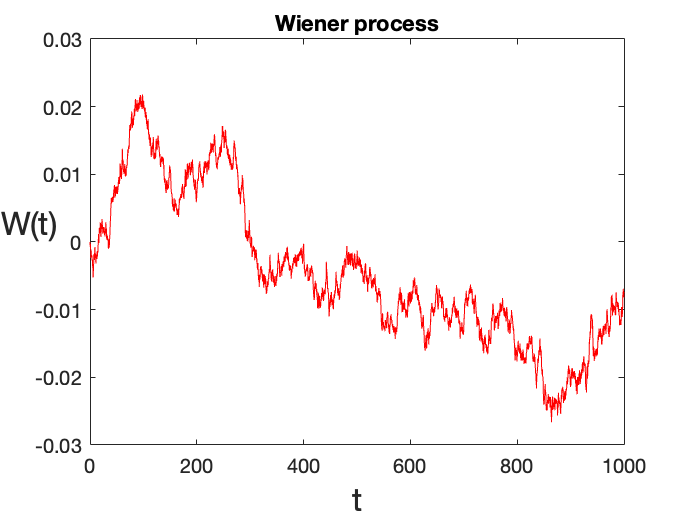

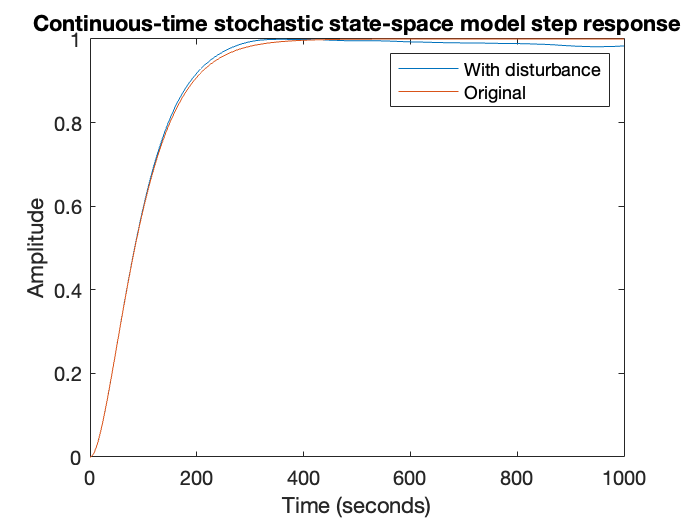

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end